# Miniprojekt 1 - tidsdomæneanalyse

## Formål

Formålet med denne første opgave er, at blive fortrolig med Matlab til at håndtere, plotte og analysere digitale signaler.

Vi vil starte med at loade de tre lydklip der er givet i opgaven:

load('miniprojekt1_lydklip.mat');

## Signal 1

### 1. Signal aflyttes

Vi vil starte med at lytte til signalet.

soundsc(s1,fs_s1)
clear sound %Stopper afspilningen

### 2. Bestemmlse af antal samples

Antallet af samples bestemmes i signalet.

s1_len=length(s1)

s1_len = 1323000

Vi ser at der er 1323000 samples i signalet.

### 3. Signal plot

Signalet plottes med en tidsakse i sekunder.

Først beregnes sample periode tiden med formlen:


$$\textrm{Ts}=\frac{1}{\textrm{Fs}}$$


Ts_s1=1/fs_s1

Ts_s1 = 2.2676e-05

Et array over alle elemneter laves:

n_s1=0:s1_len-1;

Nu kan signalet plottes:

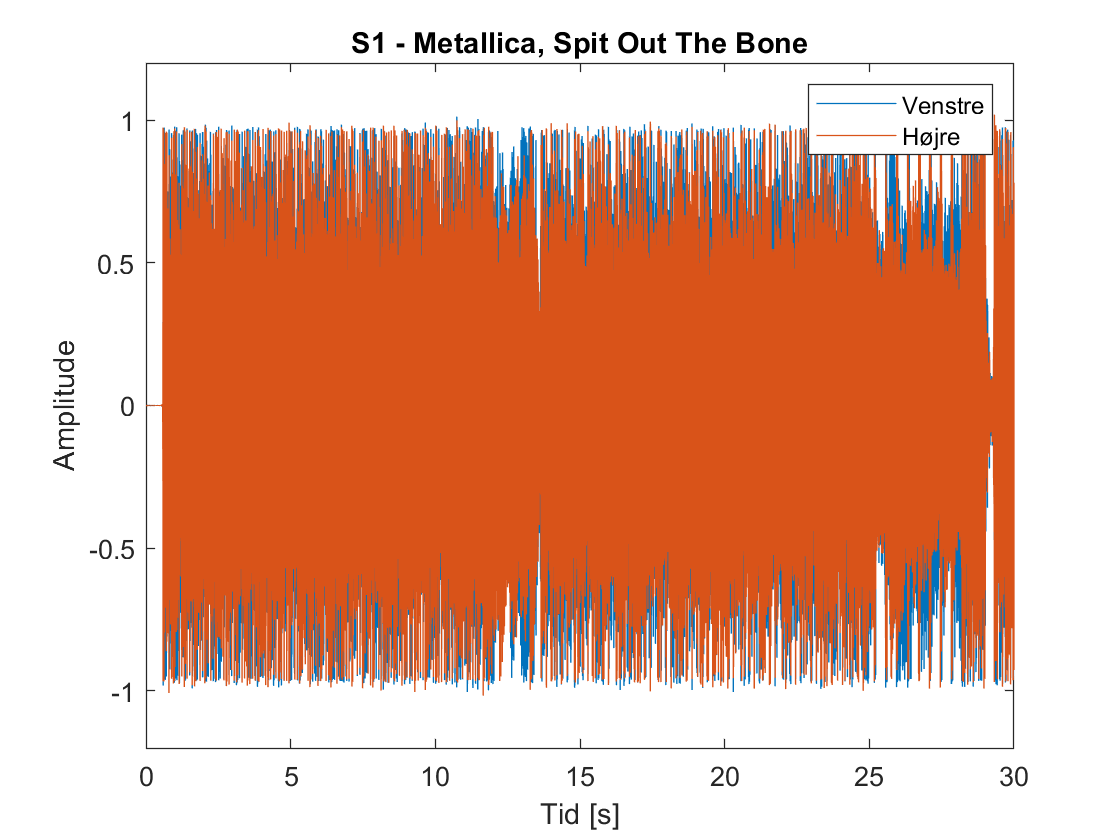

plot(n_s1*Ts_s1,s1)
title('S1 - Metallica, Spit Out The Bone')
xlabel('Tid [s]')
ylabel('Amplitude')
legend('Venstre', 'Højre')
ylim([-1.2 1.2])
hold off

Plottet er nu påvist.

### 4. Bestemmelse af min- og max-værdi, rms-værdi og energi

Min-værdien bestemmes for signalet:

s1_min=min(s1)

s1_min =    -1.0038   -1.0166


Dermed er min-værdien fundet for hver kanal i signalet. nu findes max-værdien:

s1_max=max(s1)

s1_max =     1.0190    1.0191


Max-værdien er nu fundet for hvert af de to kanaler. Nu findes RMS-værdien. Her anvendes tildligere skabt funktion:

s1_RMS=myRMS(s1)

s1_RMS = 0.3247

RMS-Værdien er findet. Nu findes energien i signalet med formlen:


$$E=\left|\sum_{n=0}^{N-1} {x\left(n\right)}^2 \right.$$


s1_E=sum(s1.^2)

s1_E = 	1.0e+05 *

    1.3952    1.1384


Dermed er energien fundet i hver kanal i Joule.

### 5. Forskelle mellem kanaler

Forskellen mellem venstre og højre kanal beregnes.

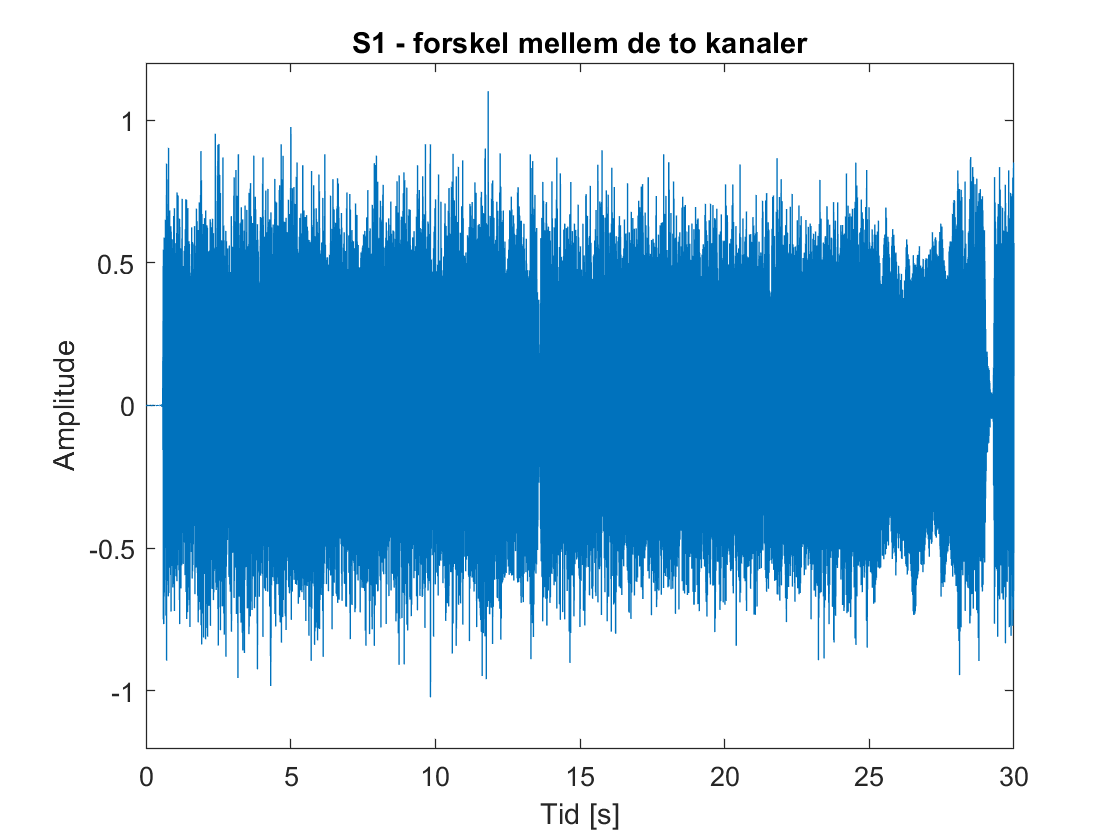

s1_left=s1(:,1);
s1_right=s1(:,2);
s1_rl_diff=s1_left-s1_right;
soundsc(s1,fs_s1)
clear sound

plot(n_s1*Ts_s1,s1_rl_diff)
title('S1 - forskel mellem de to kanaler')
xlabel('Tid [s]')
ylabel('Amplitude')
ylim([-1.2 1.2])

Nu har jeg prøvet at trække de to kanaler fra hinanden og lytte, og det lyder meget som det samlede signal. Derudover er det blevet plottet som ses ovenfor.

### 6. Nedsampling

Der laves nu en nedsampling med en faktor 4.

fs1_ny=fs_s1/4;
s1_ny=resample(s1,fs1_ny,fs_s1);
soundsc(s1_ny,fs1_ny)
clear sound

Efter vi har nedsamplet med en faktor fire ses at antallet af samples bliver reduceret. Vi oplever dermed at lydkvaliteten falder markant, hvilket også kan høres når der afspilles.

## Signal 2

### 1. Signal aflyttes

Vi vil igen starte med at lytte til signalet.

soundsc(s2,fs_s2)
clear sound %Stopper afspilningen

### 2. Bestemmlse af antal samples

Antallet af samples bestemmes i signalet.

s2_len=length(s2)

s2_len = 3360000

Vi ser at der er 3360000 samples i signalet.

### 3. Signal plot

Signalet plottes med en tidsakse i sekunder.

Først beregnes sample periode tiden med samme formel som før:

Ts_s2=1/fs_s2

Ts_s2 = 1.0417e-05

Et array over alle elemneter laves:

n_s2=0:s2_len-1;

Nu kan signalet plottes:

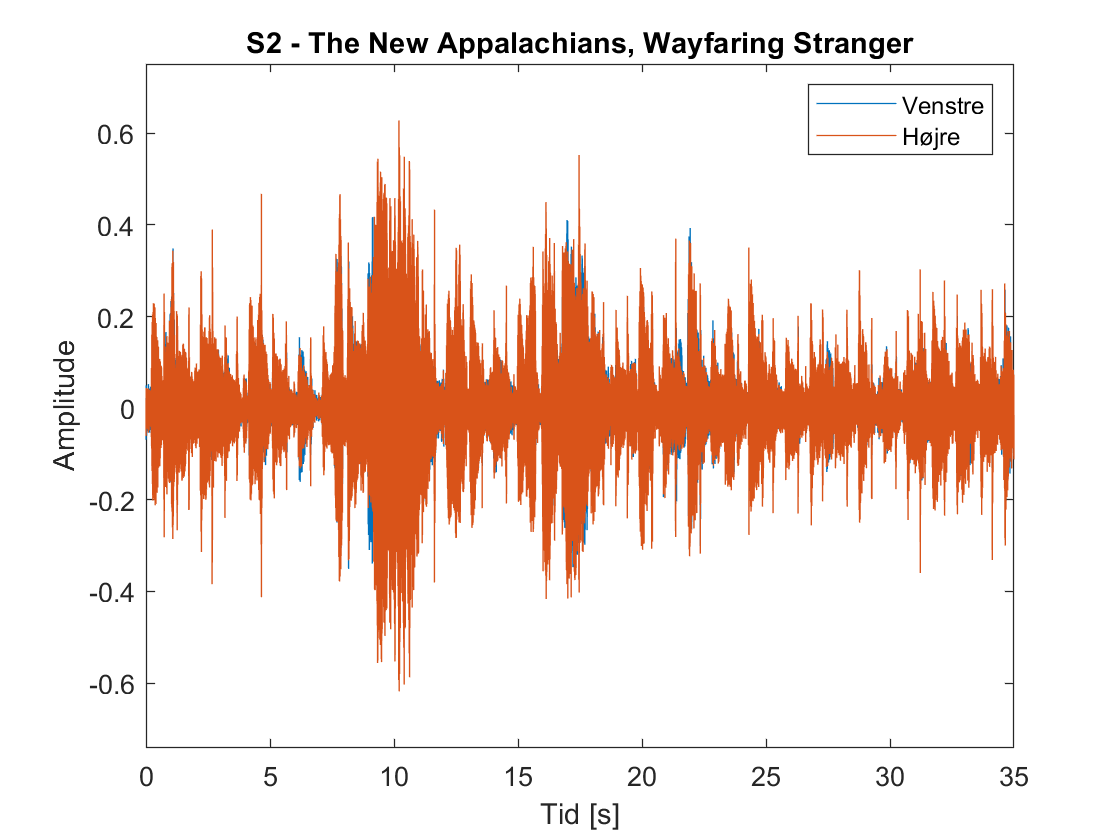

plot(n_s2*Ts_s2,s2)
title('S2 - The New Appalachians, Wayfaring Stranger')
xlabel('Tid [s]')
ylabel('Amplitude')
legend('Venstre', 'Højre')
ylim([-0.7416 0.7535])
hold off

Plottet er nu påvist.

### 4. Bestemmelse af min- og max-værdi, rms-værdi og energi

Min-værdien bestemmes for signalet:

s2_min=min(s2)

s2_min =    -0.4053   -0.6180


Dermed er min-værdien fundet for hver kanal i signalet. nu findes max-værdien:

s2_max=max(s2)

s2_max =     0.4174    0.6279


Max-værdien er nu fundet for hvert af de to kanaler. Nu findes RMS-værdien. Her anvendes tildligere skabt funktion:

s2_RMS=myRMS(s2)

s2_RMS = 0.0599

RMS-Værdien er findet. Nu findes energien i signalet med samme formel som før.

s2_E=sum(abs(s2.^2))

s2_E = 	1.0e+04 *

    1.2066    2.2575


Dermed er energien fundet i hver kanal i Joule.

### 7. Fade-out

Der laves nu et fadeout over den sidste tredjedel af signalet. Først med en lineær envelope og dernest en eksponentiel aftagende.

Først laves en Linearfade med linespace funktionen. Den start med en amplityde på 1 og slutter med 0.05 for at slutte på 5%. Da det er den sidste tredjedel, paddes der et taller  på 2/3 af samples.

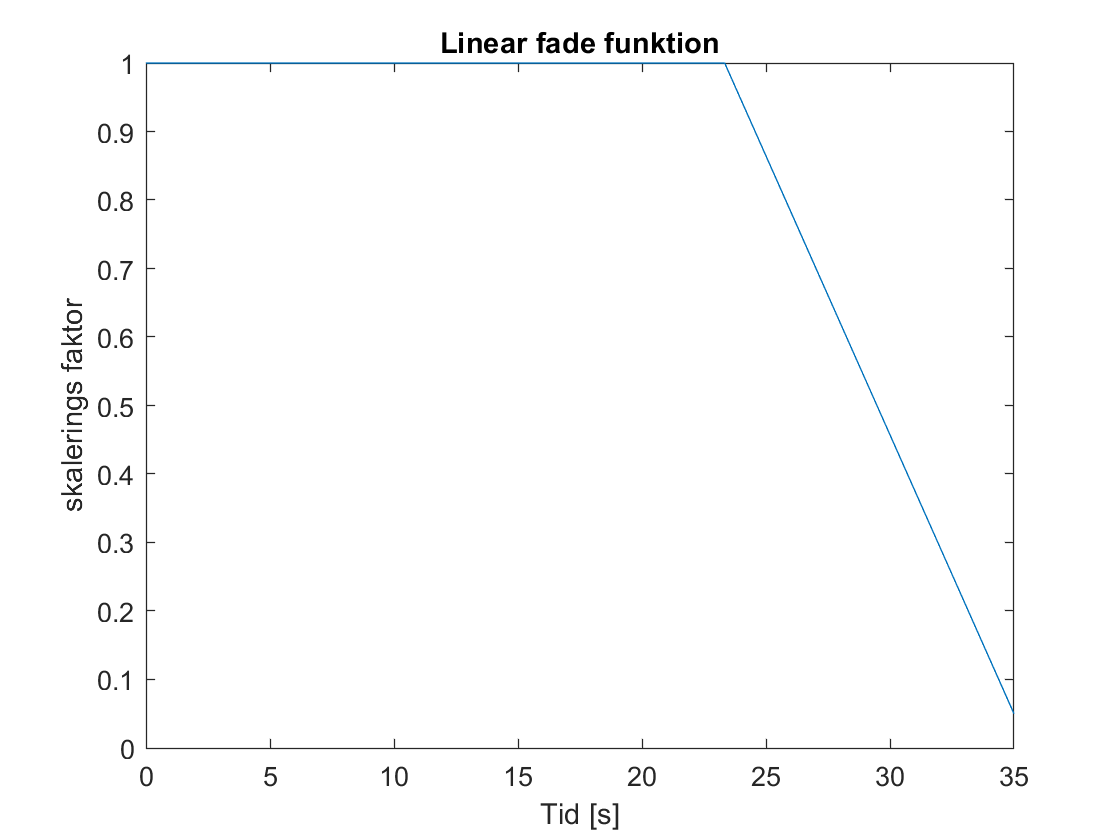

LinearFadeOut=[ones(1,s2_len*2/3) linspace(1,0.05,s2_len/3)];
LinearFadeOut=LinearFadeOut(:);
plot(n_s2*Ts_s2,LinearFadeOut)
title('Linear fade funktion')
xlabel('Tid [s]')
ylabel('skalerings faktor')
hold off

Funktionen påtrykkes nu signalet og plottes.

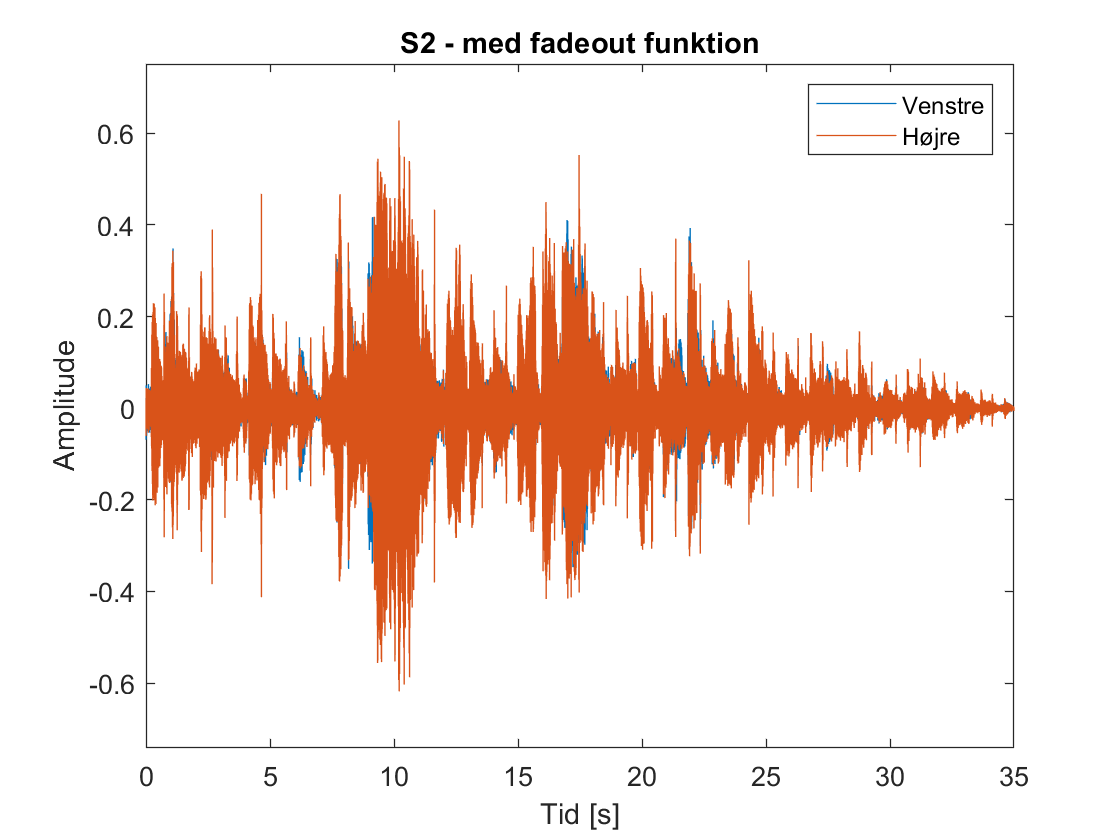

s2_fadeout=LinearFadeOut .* s2;
plot(n_s2*Ts_s2,s2_fadeout)
title('S2 - med fadeout funktion')
xlabel('Tid [s]')
ylabel('Amplitude')
legend('Venstre', 'Højre')
ylim([-0.7416 0.7535])
hold off

Nu laves den eksponentielt aftagende funktion, med samme princip som før.

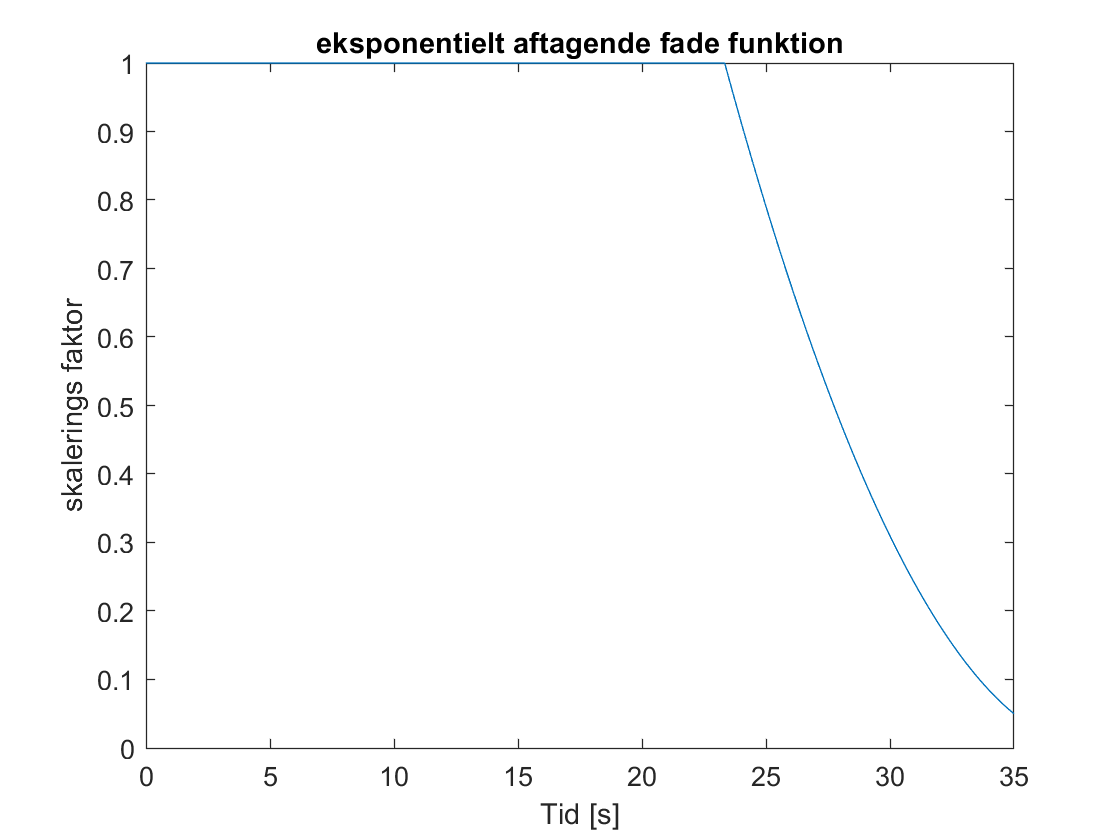

ExpFadeOut=[ones(1,s2_len*2/3) linspace(1,sqrt(0.05),s2_len/3).^2];
ExpFadeOut=ExpFadeOut(:);
plot(n_s2*Ts_s2,ExpFadeOut)
title('eksponentielt aftagende fade funktion')
xlabel('Tid [s]')
ylabel('skalerings faktor')
hold off

Funktionen påtrykkes nu signalet og plottes.

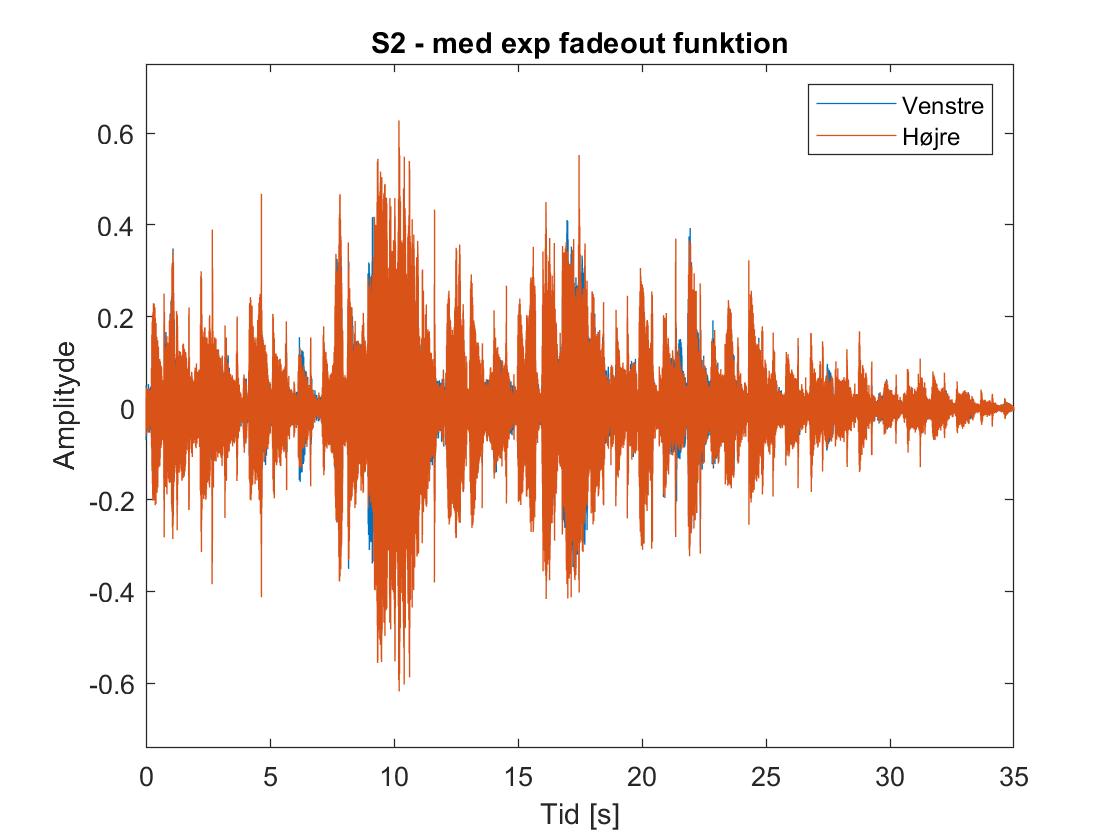

s2_expfadeout=LinearFadeOut .* s2;
plot(n_s2*Ts_s2,s2_expfadeout)
title('S2 - med exp fadeout funktion')
xlabel('Tid [s]')
ylabel('Amplityde')
legend('Venstre', 'Højre')
ylim([-0.7416 0.7535])
hold off

Nu lyttes til begge signaler:

soundsc(s2_fadeout,fs_s2)
soundsc(s2_expfadeout,fs_s2)
clear sound

Efter jeg har lyttet til vær af de to kan jeg konkludere at den eksponentielt aftagende lyder mest naturligt.

## Signal 3

### 1. Signal aflyttes

Vi vil starte med at lytte til signalet.

soundsc(s3,fs_s3)
clear sound %Stopper afspilningen

### 2. Bestemmlse af antal samples

Antallet af samples bestemmes i signalet.

s3_len=length(s3)

s3_len = 1411200

Vi ser at der er 1411200 samples i signalet.

### 3. Signal plot

Signalet plottes med en tidsakse i sekunder.

Først beregnes sample periode tiden med samme formel som før:

Ts_s3=1/fs_s3  

Ts_s3 = 2.2676e-05

Et array over alle elemneter laves:

n_s3=0:s3_len-1;

Nu kan signalet plottes:

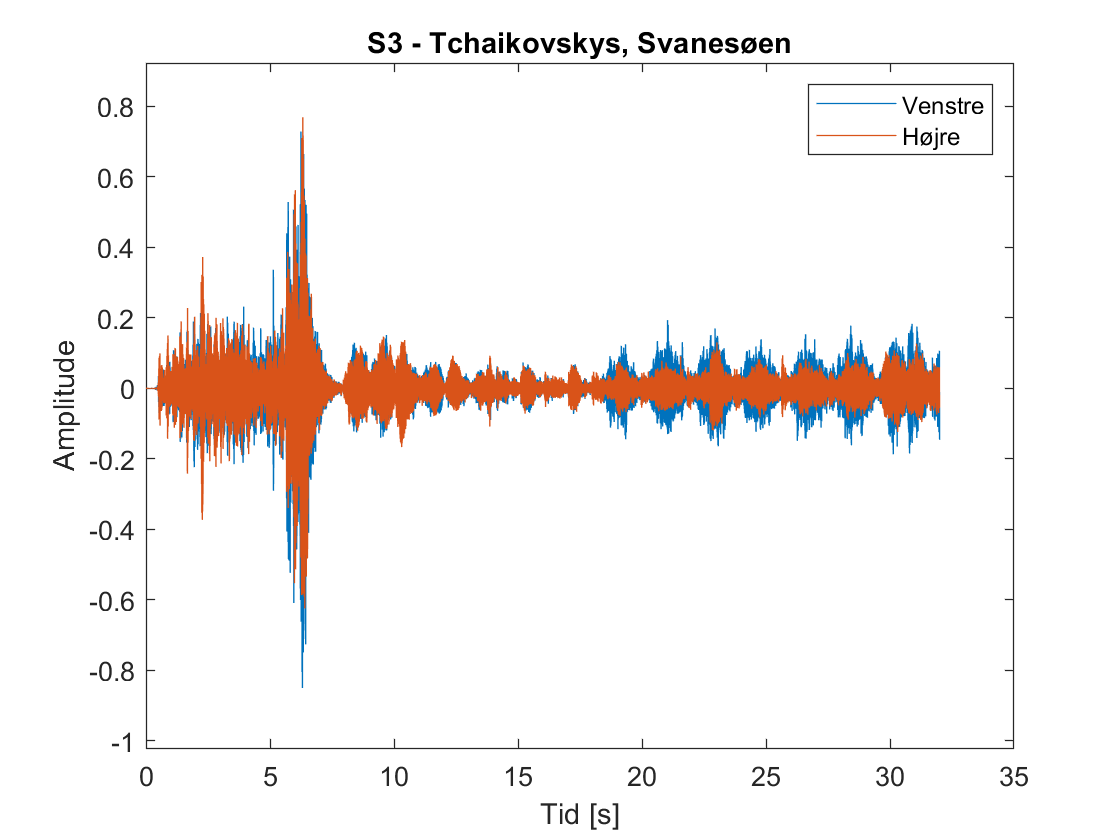

plot(n_s3*Ts_s3,s3)
title('S3 - Tchaikovskys, Svanesøen')
xlabel('Tid [s]')
ylabel('Amplitude')
legend('Venstre', 'Højre')
ylim([-1.0202 0.9229])

Plottet er nu påvist.

### 4. Bestemmelse af min- og max-værdi, rms-værdi og energi

Min-værdien bestemmes for signalet:

s3_min=min(s3)

s3_min =    -0.8502   -0.6243


Dermed er min-værdien fundet for hver kanal i signalet. nu findes max-værdien:

s3_max=max(s3)

s3_max =     0.7283    0.7691


Max-værdien er nu fundet for hvert af de to kanaler. Nu findes RMS-værdien. Her anvendes tildligere skabt funktion:

s3_RMS=myRMS(s3)

s3_RMS = 0.0467

RMS-Værdien er findet. Nu findes energien i signalet, med samme formel som før.

s3_E=sum(abs(s3.^2))

s3_E = 	1.0e+03 *

    3.0749    2.5873


Dermed er energien fundet i hver kanal i Joule.

## Konklusion

Vi kan dermed konkludere at vi kom igennem alle de opstillede opgaver. Vi har kunnet benytte Matlab og des funktioner, såsom plot og vi fik analyseret på de tre signaler, hvilket var formålet med opgven.